The following edited based on:

        Copyright (c) 2014, Josh Bevan

        All rights reserved.

        This code is licensed under the BSD 3-Clause License, see License.txt for the full license.

August 2021, Lucia Zhang

# 1D Scalar Conservation Eqn solution

*-- using Discontinuous Galerkin*

### Discretization methods

- Linear spatial disretization

- forward Euler time discretization

clear all
close all
tau = 2*pi();     % wave length of initial condition

## Problem definition

Here we attempt to solve the 1D scalar conservation eqn of the form:


$$\frac{\partial u}{\partial t} + \frac{\partial f(u)}{\partial x} = 0$$


where $f\left(u\right)$ is some flux function describing the "flow" of a conserved quantity (note that in lecture we used "$q$"). In this simplified case $f\left(u\right)=u$ giving us a linear PDE.

### Key parameters

We will use** periodic boundary conditions **to examine numerical dissipation effects:

- Let $u\left(x,t\right)$ be the exact solution on the domain $0\le x\le 1$

- Let $u\left(\ldotp ,0\right)=u_0 =\sin \left(2\pi x\right)$

- Let $V_h$ be the finite vector space of linear polynomials

- Let $U_h$ be the approximate numerical solution consisting of a linear combination of basis functions ($\theta_N$ for the $N^{\textrm{th}}$ basis) in $V_h$ with scalar coefficients `BasisWeightN` (i.e. $\sum \;$`BasisWeightN `$\theta_N$)

- Let $\phi_N$ be the $N^{\textrm{th}}$ test function in the same vector space as the basis functions (`vh`), in this simplified case N=2

Number of basis functions:

N = 2;

### Spatial discretization

Discretize the domain into K elements with K+1 nodes:

K = 8;
xNode   = 0:1/K:1;             % nodes, @boundaries of elements
deltax  = diff(xNode);         % element size
deltaxM = repmat(deltax,N,1);  % Repeat deltax for the N basis functions

All the nodes, note *there are repeats *(twice, to be specific), since nodes have a coincident brother from an adjacent element, except at the boundaries.

xh = reshape(sort([xNode,xNode(2:end-1)]),N,K)';
u  = sin(tau.*xh);             % Analytical sol'n


$$u=\sin (\tau x_h)=\sin (2\pi x_h)$$


#### Right Hand Side (exact)

According to Cockburn,Shu 2001 Eqn 2.2

         6. let uh(.,0) be computed by $\int u_h \phi = \int u_0 \phi$ for each element ($x_j-\frac{1}{2} < x < x_j+\frac{1}{2}$)

We can explicitly define a formula for the value of the RHS (Right Hand Side):

`ExactRHSN` = $\int \;u_0 \phi_N$ 

ExactRHS(1,:)=  (tau*deltax.*cos(tau.*xNode(1:end-1))+sin(tau.*xNode(1:end-1))-sin(tau.*xNode(2:end)))./(4*pi()^2.*(deltax));
ExactRHS(2,:)= -(tau*deltax.*cos(tau.*xNode(2:end)  )+sin(tau.*xNode(1:end-1))-sin(tau.*xNode(2:end)))./(4*pi()^2.*(deltax));

*            Above code in readible form:  *$\frac{\left(2\pi \Delta \textrm{xcos}\left(2\pi x_L \right)+\sin \left(2\pi x_L \right)-\sin \left(2\pi x_R \right)\right)}{4\pi^2 \Delta x}$,  $-\frac{\left(2\pi \Delta \mathrm{xcos}\left(2\pi x_R \right)+\sin \left(2\pi x_L \right)-\sin \left(2\pi x_R \right)\right)}{4\pi^2 \Delta x}$

## Split things up: Mass, Stiffness, Boundary flux

### Left Hand Side - Mass

The LHS (Left Hand Side) requires calculation of $\int \;u_h \phi \;$

- which is $\int \sum(a_N \theta_N) \phi$ (note that is equivalent to  as shown in lecture)

Matrix of LHS integrals of form $\int \;\theta_i \phi_j$

- where $\theta_i =\phi_j$

LHSIntegrals = [1/3 1/6;
                1/6 1/3];       % Recall Mass Matrix from lecture, identical in value

#### Relating Mass Matrix to Initial conditions

Calculate basis weights for approximate solution

`LHSIntegrals * BasisWeights = ExactRHS` / $\Delta x$

BasisWeights = LHSIntegrals\(ExactRHS./deltaxM);   % gives us initial BasisWeights

Now that we have $u_0$

- we can begin *explicit time stepping (****forward Euler****)* with the semi-discrete form of the PDE.

Because we have a linear flux function

- all the classic monotone flux schemes reduce to the *simple ****upwind flux*** i.e. $g\left(v-\left(x\right),\;v+\left(x\right)\right)=v-\left(x\right)$

### Assemble Semi-discrete

#### Assemble Semi-discrete matrix (local)

Let's assemble our **semi-discrete stencil**, assuming the `BasisWeight` vector is of the form


$$[ a1_j\ a2_j\ a1_{j+1}\ a2_{j+1}\ \cdots a1_K\ a2_K ]$$


UpwindFlux = [1 0  0;
              0 0 -1];
RHSIntegrals = [0 -1/2 -1/2;
                0  1/2  1/2];
Stencil = LHSIntegrals\(UpwindFlux + RHSIntegrals);

#### Assemble semi-discrete system (Global)

Stamping the stencil `Stencil`, which is for a particular element, to our global matrix `SemiMatrix`:

SemiMatrix = zeros(N*K);                    % initializing global matrix
for i=1 : size(Stencil,1) : size(SemiMatrix,2)-(size(Stencil,1)+1)
    SemiMatrix(i:i-1+size(Stencil,1),i:i-1+size(Stencil,2))=Stencil;
end

Making sure global matrix "loops" (see function `circshift` usage for further detial):

SemiMatrix = circshift(SemiMatrix, [0 -1]); % Apply periodic BC, "MATLAB fancy footwork"
SemiMatrix(end+1-size(Stencil,1):end,end+1-size(Stencil,2):end)=Stencil;
SemiMatrix = SemiMatrix./deltax(1);

Vectorizing `BasisWeights`:

BasisWeights = reshape(BasisWeights,N*K,1);
cats = BasisWeights;

### Discretize in time

#### Temporal Parameters

deltaT = .0001;
saveT  = 0.01;                 %frequency of saving sol'n approx, "sampling period"
nsaveT = floor(saveT/deltaT);
endT   = 3;
nT     = floor(endT/deltaT);
NormFreq = 100;
saved  = zeros((nT/nsaveT)+1,K*N);

#### Loop through time domain

i = 0; norm2 = [];
for t = 0:1:nT
    BasisWeights = (eye(N*K)+SemiMatrix*deltaT)*BasisWeights; % (*)
    if t/nsaveT==floor(t/nsaveT)
        if i/NormFreq == floor(i/NormFreq)
            norm2 = [norm2 sum(([u(1,1) u(:,2)']'-BasisWeights([1 2:2:end])).^2)];
        end
        i = i+1;
        saved(i,:)=BasisWeights;
    end
end

Note: Equivalently, could replace (*) line with:

- ...which might be more or less more readible XD

Saving values (as explained in lecture):

saved = reshape(saved',N,K,length(saved));

## Plotting

### Post processing

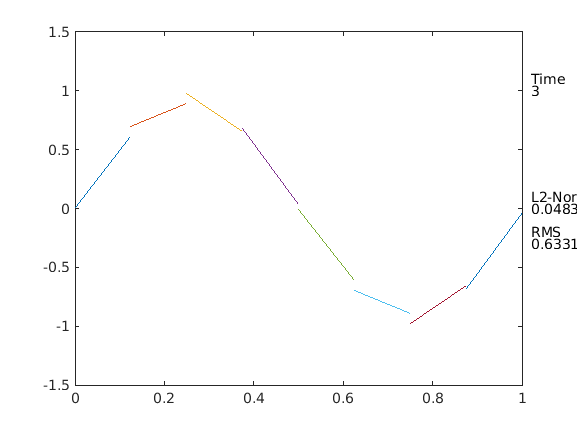

h=figure;set(gcf, 'Color','white')
% nFrames = length(saved);
% vidObj = VideoWriter('1DConvDG.avi');
% vidObj.Quality = 100;
% vidObj.FrameRate = floor(nFrames/(2*endT));
% open(vidObj);

i = length(saved); j = 0;
for i=1:length(saved)
    plot(xh',saved(:,:,i))
    axis([0 1 -1.5 1.5])
    if (i-1)/NormFreq == floor((i-1)/NormFreq)
        j=j+1;
    end
    text(1.02,0.1,'L2-Norm')
    text(1.02,0,num2str(norm2(j)));
    text(1.02,-0.2,'RMS')
    text(1.02,-.3,num2str(rms(reshape(saved(2,:,i),K,1))));
    text(1.02,1.1,'Time')
    text(1.02,1,num2str((i-1)*saveT));
    %writeVideo(vidObj, getframe(h));
    pause(.001)
end


% close(gcf)
% close(vidObj);

If need to save plot in video format, uncomment the commented lines above.